# Determine Work Envelope of Robot Arm

This example shows how to determine the work envelope of a 6-axis articulated robot.

Copyright 2023 The MathWorks, Inc.

To return to the main page within this repository, [click here](matlab:web('RobotDesignOverview.html')).

## Understand Work Envelope of Robot Arm

The work envelope or workspace area of a robotic arm is the space where the arm can move and perform tasks effectively. It represents the region in three-dimensional space that the robotic arm can access and operate within. The shape and size of the workspace area vary depending on the specific design and configuration of the robotic arm. It may be limited to a specific region or encompass a larger space, depending on the arm's capabilities and intended application. 

A robot arm workspace area is crucial for tasks such as trajectory planning, collision avoidance, and optimizing the arm's operational range. It helps ensure that the arm can reach and manipulate objects within its designated workspace effectively and safely.

## Generate Workspace for Parametric Robot

Setup the parameters for the parametric robot using Simscape Multibody™ custom libraries. Define the robot model and the rigid body representing end effector. This example determines the robot work envelope based on Body 5 (Link 4 in the parametric robot model) as the end-effector.

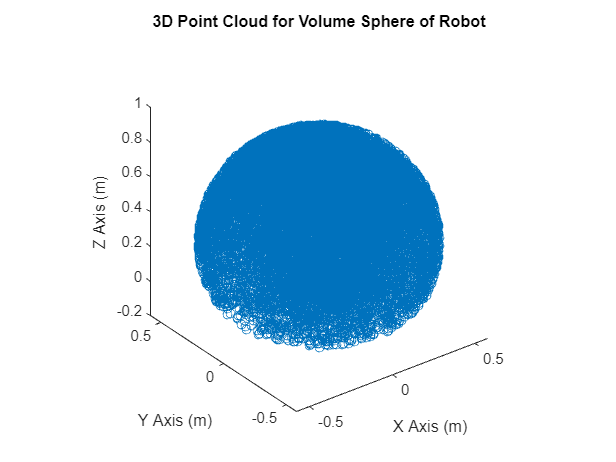

Generate the envelope of front-view


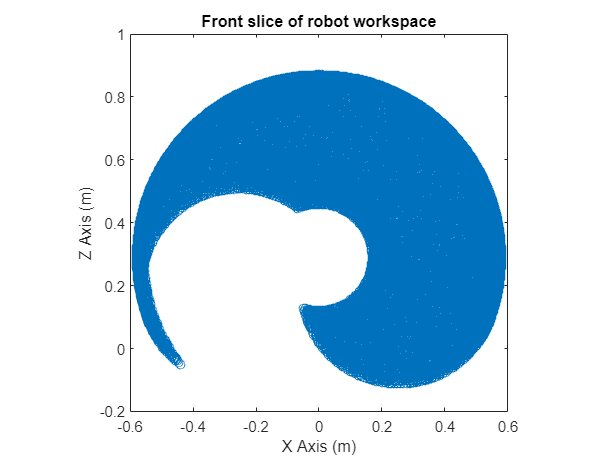

Generate the envelope of top-view


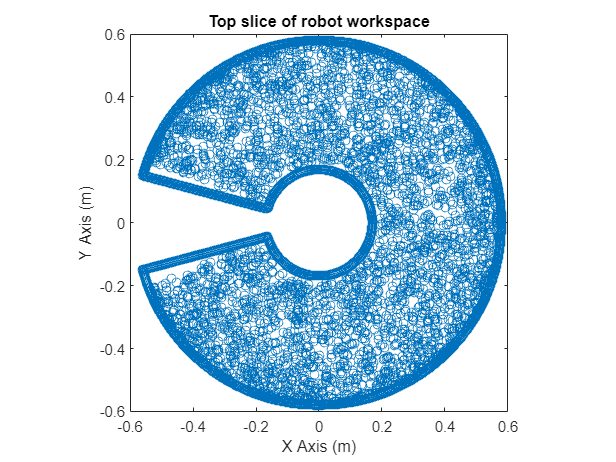

% Define the Robot model and end effector
modelRobot = 'ParametricRobotModel';
endEffectorName = "Body5";

%% Import information from the model to rigid body tree structure. 
% This information includes all the design parameters and structural 
% details of the robot.
load_system('ParametricRobotModel.slx');
run('ParametricRobotParameters');
robot = importrobot(modelRobot);
close_system(modelRobot);
robot.DataFormat = 'column';

% Run envelope generator script, read the comments in the scripts for
% better understanding
[outerParams_Parametric, innerParams_Parametric] = envelopeGenerator(robot, endEffectorName);

filepath = mlreportgen.utils.findFile("workspaceParametricRobotModel.mat")

filepath = "L:\Project2024b\Abir_Robot_feedback\Workflow\ActuatorRating\Data\workspaceParametricRobotModel.mat"

save(filepath,'outerParams_Parametric','innerParams_Parametric');
fprintf(' Outer/max radius of reach (m): %d.\n Inner/Min radius of reach (m): %d. \n',outerParams_Parametric(1),innerParams_Parametric(1));

 Outer/max radius of reach (m): 5.797941e-01.
 Inner/Min radius of reach (m): 1.676538e-01. 


## Useful Links

For comparison of workspace of CAD and parametric robot see [CompareEnvelope](matlab:open('CompareEnvelope.mlx')).

You can size the electrical actuation components for a known work envelope and payload weight. To learn more about sizing electrical actuation components, see [ActuatorRatingWorkflow](matlab:open('ActuatorRatingWorkflow.mlx')).